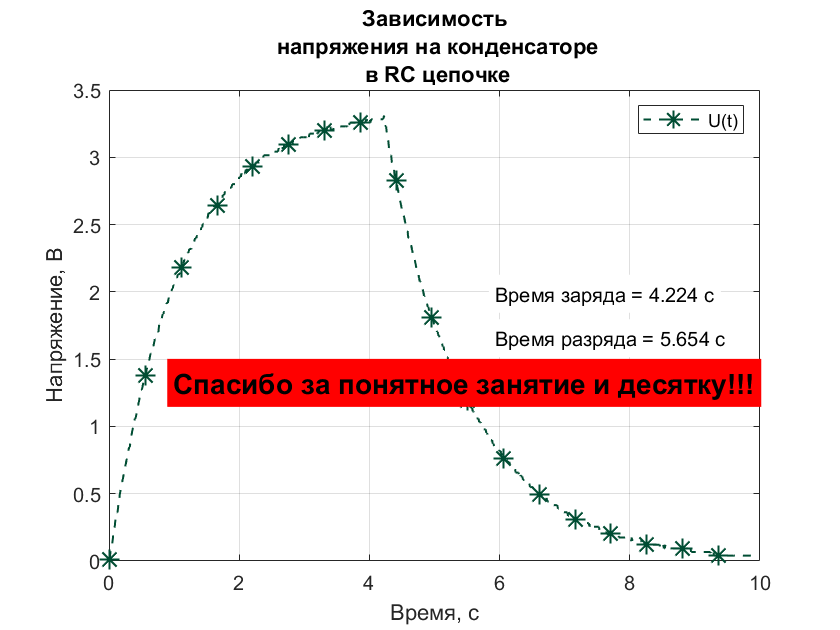

close all;
clear variables;

data = importdata('data.txt');
scale = importdata('settings.txt');

dV = scale(1);
dt = scale(2);

U = data * dV;
[maxU, abc] = max(U);

t = ((1:length(data)) * dt)';

tCharge = abc * dt;
tDischarge = length(data) * dt - tCharge;

f1 = figure("Name", 'Rytova Alena Б03-006');
plot(t, U, 'g--*', 'MarkerIndices', 1:50:length(U), 'LineWidth', 1, 'MarkerSize', 10, 'Color', [0, 0.3, 0.2]);
grid on;
set(gcf, 'Visible', 'on');
title({'Зависимость',' напряжения на конденсаторе', ' в RC цепочке'});
xlabel('Время, с');
ylabel('Напряжение, В');
legend('U(t)');
text(max(t) * 0.6, max(U) * 0.6, ['Время заряда = ', num2str(tCharge), ' с'], 'BackgroundColor', 'w');
text(max(t) * 0.6, max(U) * 0.5, ['Время разряда = ', num2str(tDischarge), ' с'], 'BackgroundColor', 'w');
text(max(t) * 0.1, max(U) * 0.4, ['Спасибо за понятное занятие и десятку!!!'], 'FontSize', 14, 'FontWeight',"bold", 'BackgroundColor', 'r');

saveas(f1, 'capitator.png');
saveas(f1, 'capitator.svg');